# 数学

a = 1:10

a =      1     2     3     4     5     6     7     8     9    10


### 魔方数据

b = magic(6)

b =     35     1     6    26    19    24
     3    32     7    21    23    25
    31     9     2    22    27    20
     8    28    33    17    10    15
    30     5    34    12    14    16
     4    36    29    13    18    11


### P1_1_1  绝对值函数的图像

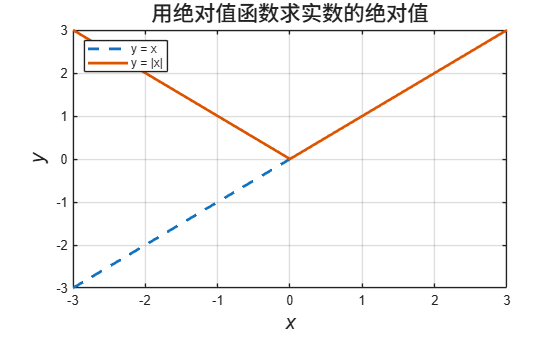

clear;
xm = 3;
x = -xm:0.1:xm;       % 修正1：生成从 -3 到 3、步长为 0.1 的数组

y = abs(x);
figure;
p = plot(x, x, '--', x, y);   % 修正2：去掉 '--' 中间的空格
set(p, 'LineWidth', 2);       % 让两条曲线同时加粗

grid on;
title('用绝对值函数求实数的绝对值', 'FontSize', 16);
xlabel('\itx', 'FontSize', 16);
ylabel('\ity', 'FontSize', 16); % 修正3：补上反斜杠 '\it' 使 y 变为斜体
legend('y = x', 'y = |x|', 'Location', 'northwest'); % 补充图例方便区分两条线

### 1.符号函数的使用

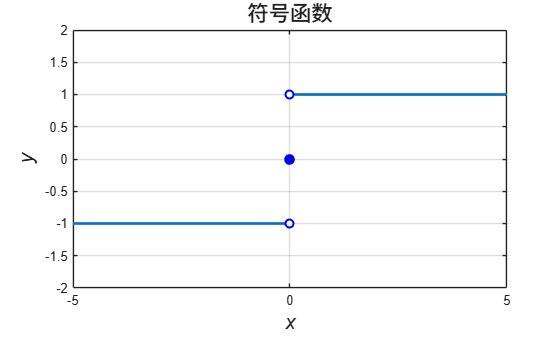

clear;
xm = 5;
x = -xm:0.1:xm;                % 生成从 -5 到 5、步长为 0.1 的数组
y = sign(x);
y(abs(x) < 1e-10) = nan;       % 修正1：用容差判断替代 x == 0，防止浮点误差导致零点未断开

figure;                        % 修正2：将点号改为分号
plot(x, y, 'LineWidth', 2);
hold on;
plot(0, 1, 'bo', 0, -1, 'bo', 'LineWidth', 1.5, 'MarkerFaceColor', 'w'); % 修正3：将 0.1 改为 0, 1，画出空心端点
plot(0, 0, 'b.', 'MarkerSize', 24);                                      % 画出 (0, 0) 处的实心定义点

title('符号函数', 'FontSize', 16);
xlabel('\itx', 'FontSize', 16);
ylabel('\ity', 'FontSize', 16);
grid on;
axis([-xm, xm, -2, 2]);
hold off;

### 2.取整函数

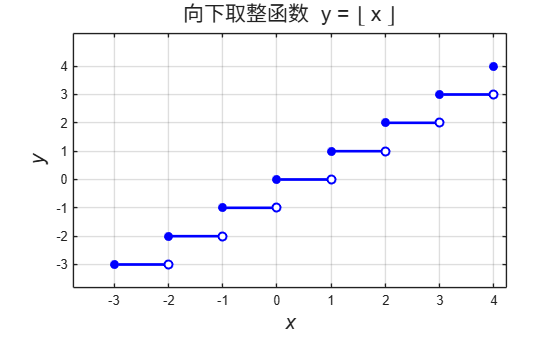

clear;
xm = 4;                        % 设置 X 轴范围为 [-4, 4]
x = -xm:0.01:xm;               % 步长取 0.01 使阶梯边缘足够精细
y = floor(x);

% 1. 在所有整数间断点处插入 NaN，防止 MATLAB 自动画出垂直连线
% 判断条件：x 非常接近整数，且不是右边界端点
is_int = abs(x - round(x)) < 1e-10;
y(is_int) = nan;

figure;
plot(x, y, 'b-', 'LineWidth', 2);
hold on;

% 2. 绘制每个阶梯的端点符号
k_left  = -xm : xm-1;          % 左端点整数序列 [-4, -3, ..., 3]
k_right = -xm+1 : xm;          % 右端点整数序列 [-3, -2, ..., 4]

% 左端点为实心点 (如 x=1 时, y=1 包含在内)
plot(k_left, k_left, 'b.', 'MarkerSize', 20);

% 右端点为空心圆 (如 x 趋近于 1- 时, y=0 不包含该点)
plot(k_right, k_right - 1, 'bo', 'LineWidth', 1.5, 'MarkerFaceColor', 'w', 'MarkerSize', 6);

% 3. 补充右边界 (xm, xm) 处的实心定义点
plot(xm, xm, 'b.', 'MarkerSize', 20);

% 4. 图表格式与公式标注
title('向下取整函数  y = \lfloor x \rfloor', 'FontSize', 16);
xlabel('\itx', 'FontSize', 16);
ylabel('\ity', 'FontSize', 16);
grid on;
axis([-xm, xm, -xm-0.5, xm+0.5]);
set(gca, 'XTick', -xm:xm, 'YTick', -xm:xm); % 强制坐标轴刻度显示为整数
hold off;

xlim([-3.76 4.24])
ylim([-3.8 5.2])